# 计算Ground Truth

## 导入观测数据

jIndex = {1 2 3 4 5 6 7 8 9 10 11};
[jLat, jLng, jFlag, jAlt] = jIndex{:};

FlagTable = sort(unique(data(:,jFlag)),'descend')

FlagTable = 4


% 0：无定位，1：单点定位，2：差分定位，4：RTK固定，收敛，5：RTK 浮点
if FlagTable(1) == 0
    error('No position')
else
    dataIndex = find(data(:,jFlag) == 4);
    if isempty(dataIndex)
        dataIndex = find(data(:,jFlag) == FlagTable(1));
    end
end
size(data,1)

ans = 319

size(dataIndex,1)

ans = 319

size(dataIndex,1)/size(data,1)

ans = 1

data = data(dataIndex,:);

AverData = mean(data,1);
LLADDD = [floor(AverData(jLat:jLng)/100)+mod(AverData(jLat:jLng),100)/60 AverData(jAlt)]

LLADDD =    30.5113  114.4026   36.6936



% Tag: 30.5111196984741	114.400952872416	55.5501552447553  1
% 30.5111525269941	114.401060902533	56.3913333333333 2
% 30.5111710221533	114.401131484398	52.4061173848440 2 673/777=0.8662
% 30.5114363803850	114.401163298368	68.0964522924411 2 807/807=1
% 30.5112909666485	114.401147486021	58.2640084033613 2 119/652=0.1825
% 30.5113049545911	114.401055406072	55.2210928381963 4 377/735=0.5129
% 30.5111640582291	114.401060404306	62.7457613997879 1 943/947=0.9958
% 30.5113162834679	114.401173782164	54.2275414634146 5 410/410=1
%----------------------------------------------------------------------------

% |_________________________________|
% |---------------------------------|_
% |                                 |_·4
% |                                 |
% |                                 |_
% |                                 |_|
% |---------------------------------| .7
% |`````````````````````````````````|
% |                             |   
% |.____._______________________|   .3.5 
%  1   2&6

% 1 30.5112232015177	114.402491219736	37.1711806451613 4 310 1
% 2 30.5112249155223	114.402509777809	37.1744076433121 4 157 0.5164
% 3 30.5112439041824	114.402644105614	36.6384794952681 4 317 1
% 4 30.5113556890497	114.402633660280	38.4922774869110 4 382 1
% 5 30.5112448411470	114.402654869779	36.7614635193133 4 466 1
% 6 30.5112251791710	114.402509376449	37.2481521035599 4 309 1
% 7 30.5112698559572	114.402648260037	36.6935924764890 4 319 1




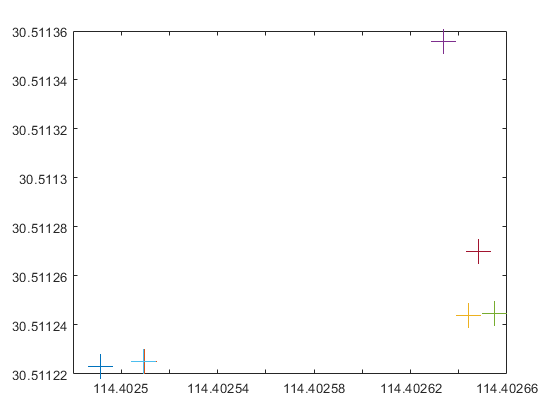

% Position = [    30.5111196984741	114.400952872416	55.5501552447553;
%                 30.5111525269941	114.401060902533	56.3913333333333;
%                 30.5111710221533	114.401131484398	52.4061173848440;
%                 30.5114363803850	114.401163298368	68.0964522924411;
%                 30.5112909666485	114.401147486021	58.2640084033613;
%                 30.5113049545911	114.401055406072	55.2210928381963;
%                 30.5111640582291	114.401060404306	62.7457613997879;
%                 30.5113162834679	114.401173782164	54.2275414634146;];

Position = [    30.5112232015177	114.402491219736	37.1711806451613; 
                30.5112249155223	114.402509777809	37.1744076433121; 
                30.5112439041824	114.402644105614	36.6384794952681; 
                30.5113556890497	114.402633660280	38.4922774869110; 
                30.5112448411470	114.402654869779	36.7614635193133; 
                30.5112251791710	114.402509376449	37.2481521035599; 
                30.5112698559572	114.402648260037	36.6935924764890; ];


p = [Position(:,2) Position(:,1)]';
figure
for i=1:size(p,2)
    plot(p(1,i),p(2,i),'+','MarkerSize',18)
hold on
end
hold off

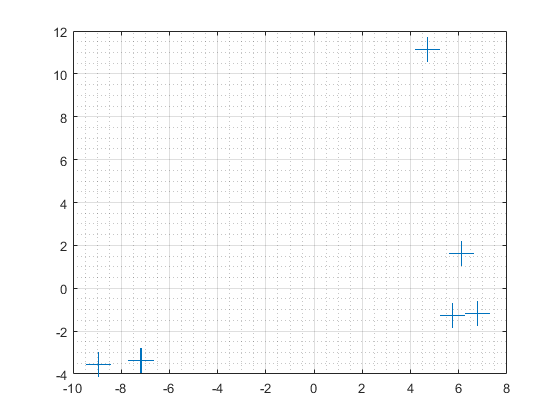


llaAver = mean(Position,1);%median position
nedM = Lla2Ned(Position,llaAver);%keep the NaNs in for the plot
%so we see a break in the lines where there was no position
figure
h = plot(nedM(:,2),nedM(:,1),'+','MarkerSize',18);
grid on
grid minor

lat = mean(Position([1 2 6 3 5],1));
lng = mean(Position([4 5 7],2));

Position(1,1) = lat;
Position(2,1) = lat;
Position(3,1) = lat;
Position(5,1) = lat;
Position(6,1) = lat;

Position(4,2) = lng;
Position(5,2) = lng;
Position(7,2) = lng;

llaAver = mean(Position,1);%median position
nedM = Lla2Ned(Position,llaAver);%keep the NaNs in for the plot
%so we see a break in the lines where there was no position
figure
h1 = plot(nedM(:,2),nedM(:,1),'b+','MarkerSize',18);
hold on
w0 = nedM(7,2)-nedM(1,2) + 1

w0 = 15.8184

h0 = nedM(4,1)-nedM(7,1) + 1.5

h0 = 11.0156

x0 = nedM(1,2)-1;
y0 = nedM(7,1);
rectangle('Position',[x0,y0,w0,h0])
w1 = nedM(7,2)-nedM(1,2)

w1 = 14.8184

h1 = nedM(4,1)-nedM(7,1)

h1 = 9.5156

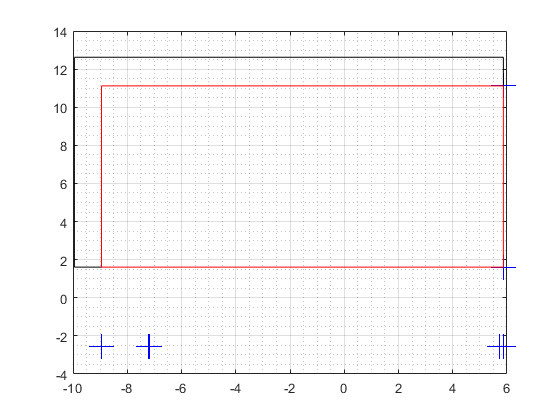

x1 = nedM(1,2);
y1 = nedM(7,1);
rectangle('Position',[x1,y1,w1,h1],'EdgeColor','r')
grid on
grid minor
hold off

% |---------------------------------|
% |  ·             ·             ·  |
% |                                 |
% |  ·             ·             ·  |
% |                                 |
% |  ·             ·             ·  |
% |---------------------------------|


llaA =  [Position(7,1) Position(1,2)];
llaB =  [Position(4,1) Position(4,2)];
llaC =  [Position(7,1) Position(4,2)];


%    B
% A  C
iA = 1;iB = 2; iC = 3;
Altitude = 37.1711806451613;
Beacon = [
    llaA;
    llaB;
    llaC
];
Beacon = [Beacon ones(3,1)*Altitude]

Beacon =    30.5113  114.4025   37.1712
   30.5114  114.4026   37.1712
   30.5113  114.4026   37.1712


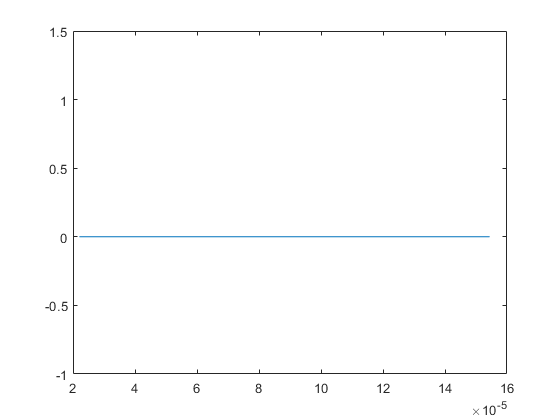


Wid = 14 ;
High = 10;

Nx = 3; Ny = 3;
Testpoint_x = [2 9 14]; % 0.7 = 0.5 + 0.2
Testpoint_y = (1:4.5:High);

dx = (Beacon(iC, 1:2) - Beacon(iA, 1:2)) ./ Wid;
dy = (Beacon(iB, 1:2) - Beacon(iC, 1:2)) ./ High;

point_x = ones(Ny, Nx);
point_y = ones(Ny, Nx);

for j=1:Nx
    for i=1:Ny
        position = Testpoint_x(j) * dx + Testpoint_y(i) * dy;
        point_x(i,j) = position(2);
        point_y(i,j) = position(1);        
    end
end

figure
plot(point_x(1,:), point_y(1,:));

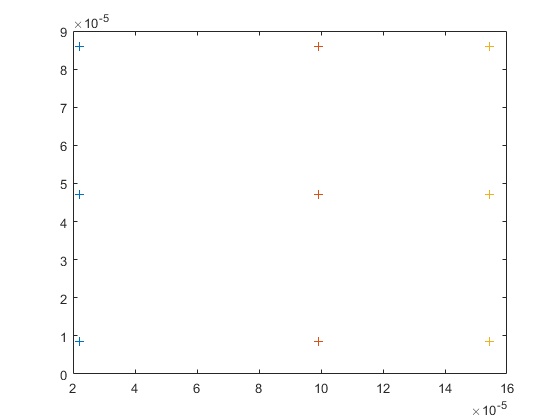

figure
plot(point_x, point_y,'+');


posx = Beacon(iA,2) + point_x;
posy = Beacon(iA,1) + point_y;

% pos
% x/y =
% 1   6   11 ...
% 2   7   12 ...
% 3   8   13 ...
% 4   9   14 ...
% 5   10  15 ...

% postionAll = [(1:Nx*Ny)'  posy(:) posx(:)];
postionAll = [(1:Nx*Ny)' posy(:) posx(:) ones(Nx*Ny, 1)*Altitude];
DirName = './C12ES';
dlmwrite([DirName '/' 'groundTruth.txt'],postionAll,'delimiter','\t','precision', 16,'newline','pc');



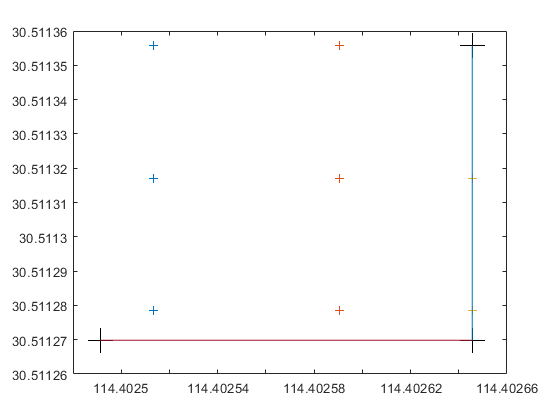

% figure
% plot(postionAll(:,2),postionAll(:,3),'+')
figure
plot(posx,posy,'+')
hold on
plot(Beacon(iA,2), Beacon(iA,1),'+k','MarkerSize',18);
hold on
plot(Beacon(iB,2), Beacon(iB,1),'+k','MarkerSize',18);
hold on
plot(Beacon(iC,2), Beacon(iC,1),'+k','MarkerSize',18);
hold on
plot(Beacon([iA iC],2), Beacon([iA iC],1))
hold on
plot(Beacon([iC iB],2), Beacon([iC iB],1))